clear;

joint_start_pos=179;
%open_system('lex_pendulum.slx');

obsInfo = rlNumericSpec([5 1],...
    'LowerLimit',[-inf -inf -inf -inf -inf]',...
    'UpperLimit',[ inf  inf  inf  inf inf]');
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured height';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1],...
    'LowerLimit',-30,...
    'UpperLimit',30');
actInfo.Name = 'action';
%numActions = numel(actInfo);
numActions = 1;

env = rlSimulinkEnv('lex_pendulum','lex_pendulum/RL Agent',...
    obsInfo,actInfo);

env.ResetFcn = @(in)localResetFcn(in);

Ts = 0.05;
Tf = 20;

rng(0);

statePath = [
    imageInputLayer([numObservations 1 1], 'Normalization', 'none', 'Name', 'State')
    fullyConnectedLayer(400, 'Name', 'CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(300, 'Name', 'CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1], 'Normalization', 'none', 'Name', 'Action')
    fullyConnectedLayer(300, 'Name', 'CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name', 'add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1, 'Name', 'CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

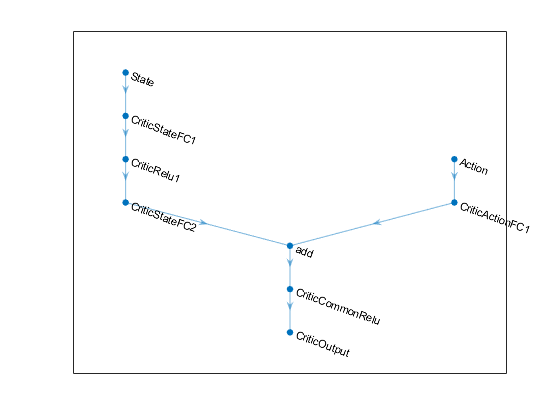

figure
plot(criticNetwork)

criticOpts = rlRepresentationOptions('LearnRate',1e-02,'GradientThreshold',1,'UseDevice',"gpu");

critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

actorNetwork = [
    imageInputLayer([numObservations 1 1], 'Normalization', 'none', 'Name', 'State')
    fullyConnectedLayer(400, 'Name', 'actorFC1')
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(300, 'Name', 'ActorFC2')
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(1, 'Name', 'ActorFC3')
    tanhLayer('Name', 'actorTanh')
    fullyConnectedLayer(numActions, 'Name', 'Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1,'UseDevice',"gpu");

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

%figure
%plot(actorNetwork)

numGPUs = 6;
miniBatchSize = 256*numGPUs;
agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',miniBatchSize, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);
%error('Script episode reached. Stop.')

%train
maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'UseParallel', true, ...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',300,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',300);
%trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 100;
%trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";
%trainOpts.ParallelizationOptions;

%doTraining = false;
    

doTraining = true;
if doTraining
    % Train the agent.
    %load('rl5с.mat','agent');
    trainingStats = train(agent,env,trainOpts);
    save('rl5с.mat','agent');    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


> In Simulink.SimulationInput/sim
  In rl.env.SimulinkEnvWithAgent/simWrapper (line 325)
  In rl.env.SimulinkEnvWithAgent/simWithPolicy (line 529)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

if doTraining==false
    % Load pretrained agent for the example.
    load('rl5с.mat','agent');
end

%validate
rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent);

%error('Script episode reached. Stop.');

function in = localResetFcn(in)
    joint_start_pos=180+rand*6-3;
    blk = 'lex_pendulum/pendulum environment/EncoMot';
    in.setBlockParameter(blk,'Value',num2str(joint_start_pos));
end